# Create a motion correction object (iteration 1)

## Recording info

% Motion correction folder of this probe
mcDir = 'D:\preproc\mc_workspace\NP134_B2_g0_imec0';

% Path to the folder where MTracerTrace files are saved
trDir = fullfile(mcDir, 'MTracer_NP134_B2_2025-11-07_14-22-57');

% Duration of this recording
tEnd = 3778.728; % sec

% Full depth of the probe
yEnd = 7660; % um

% Python traces output folder
pyTrDir = fullfile(mcDir, "motion");

## Load the traces

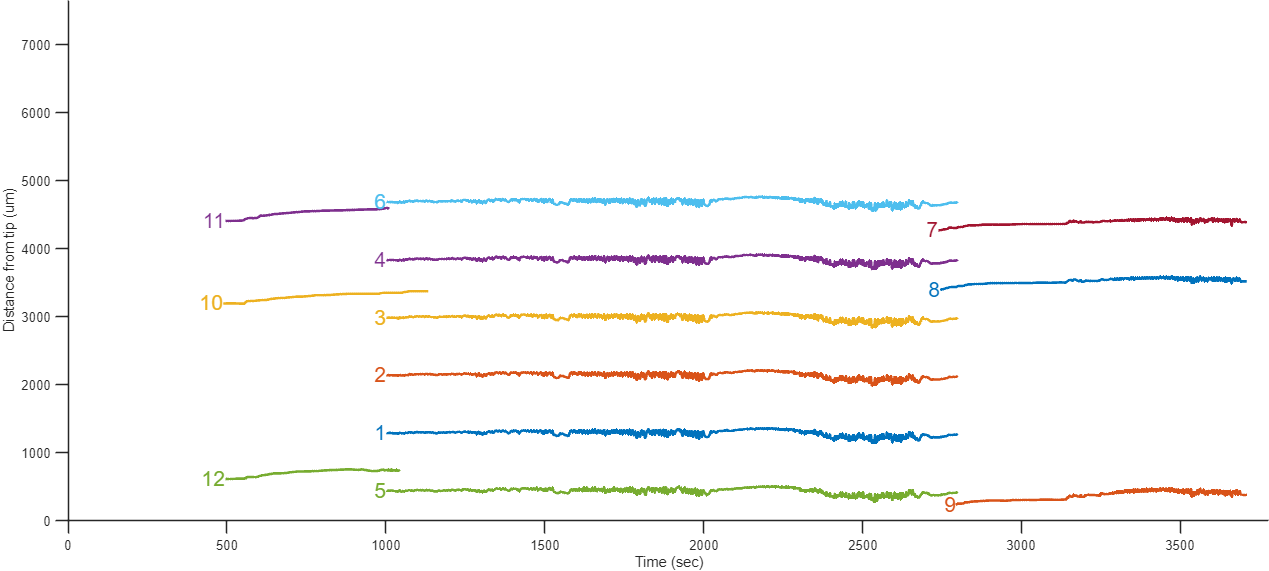

% Find trace files
trSearch = MBrowse.Dir2Table(fullfile(trDir, 'MTracerTrace*.mat'));
trPaths = fullfile(trSearch.folder, trSearch.name);

% Load traces
tbTr = table;
for i = numel(trPaths) : -1 : 1
    load(trPaths{i});
    dataTb = sortrows(dataTb, 't');
    ind = dataTb.isDone;
    tbTr.time{i} = dataTb.t(ind);
    tbTr.y{i} = dataTb.y(ind);
end

% Resample traces
tWin = [0 tEnd];
tBin = 0.02;
tbTr = NP.Motion.ResampleTraces(tbTr, tWin(1) : tBin : tWin(2));

% Plot traces with labels
f = MPlot.Figure(301); clf
f.Position(3:4) = [1600 720];
NP.Motion.PlotTraces(tbTr.time, tbTr.Y, 'ShowLabel', true);
xlim(tWin)
ylim([0 yEnd])

## Fit models for movement scaling across depth

Play with the following variables to achieve reasonable scaling.

- ind: The indices of traces to include. They should have decent amount of overlaps in time.

- scaleMathod: 'makima' for nonlinear scaling and 'linear' for linear scaling.

See function help for more details.

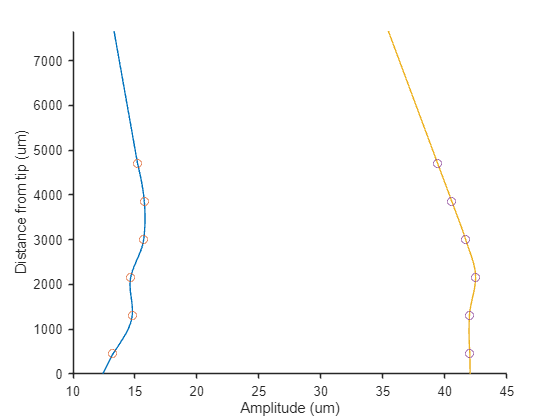

% Specify the traces we want to use for the fits
ind = [1:6];

% Fit scaling models
scaleMathod = 'makima';
[F1fluc, F1drift] = NP.Motion.FitAmpScaling(tbTr.Y(:,ind), 1/tBin, scaleMathod);

% Plot the two scaling functions
MPlot.Figure(401); clf
NP.MotionPlot.AmpScaling(F1fluc); % blue
NP.MotionPlot.AmpScaling(F1drift); % yellow

Save the models to "F1.mat" if we are happy about them

save(fullfile(mcDir, 'F1'), 'F1fluc', 'F1drift');

## Extrapolate traces

% Extrapolation
t = tbTr.time;
Y = tbTr.Y(:,[1:6 8:10 12]);
Ye = NP.Motion.ExtrapolateTraces(Y, F1fluc, F1drift);  % use both fluctuation and drift scaling model
% Ye = NP.Motion.ExtrapolateTraces(Y, F1fluc, 1);        % use fluctuation scaling model only
% Ye = NP.Motion.ExtrapolateTraces(Y, 1, F1drift);       % use drift scaling model only

% Fill the rest with straight lines
Ye = NP.Motion.ExtrapolateTrace(Ye, zeros(size(t)), F1fluc);

% Make a new table
tbTrExt = tbTr;
tbTrExt.Y = Ye(:,:); % only keep key traces

## Fit spatial-temporal interpolant

Edit the following variables for the current recording.

- t0: Where in time (sec) do we want to register everywhere else to.

% Where in time (sec) do we want to register everywhere else to
t0 = 2149;

% Construct 2D displacement field
F2 = MTracer.MotionInterpolant(t, tbTrExt.Y, t0);

% Save the object
save(fullfile(mcDir, 'F2'), 'F2');

% Save Python motion traces
if isfolder(pyTrDir)
    rmdir(pyTrDir, 's');
else
    mkdir(pyTrDir);
end
F2.Export(pyTrDir);

Motion data exported to:
  D:\preproc\mc_workspace\NP134_B2_g0_imec0\motion\temporal_bins_s_seg0.npy
  D:\preproc\mc_workspace\NP134_B2_g0_imec0\motion\spatial_bins_um.npy
  D:\preproc\mc_workspace\NP134_B2_g0_imec0\motion\displacement_seg0.npy


## Plot motion estimation

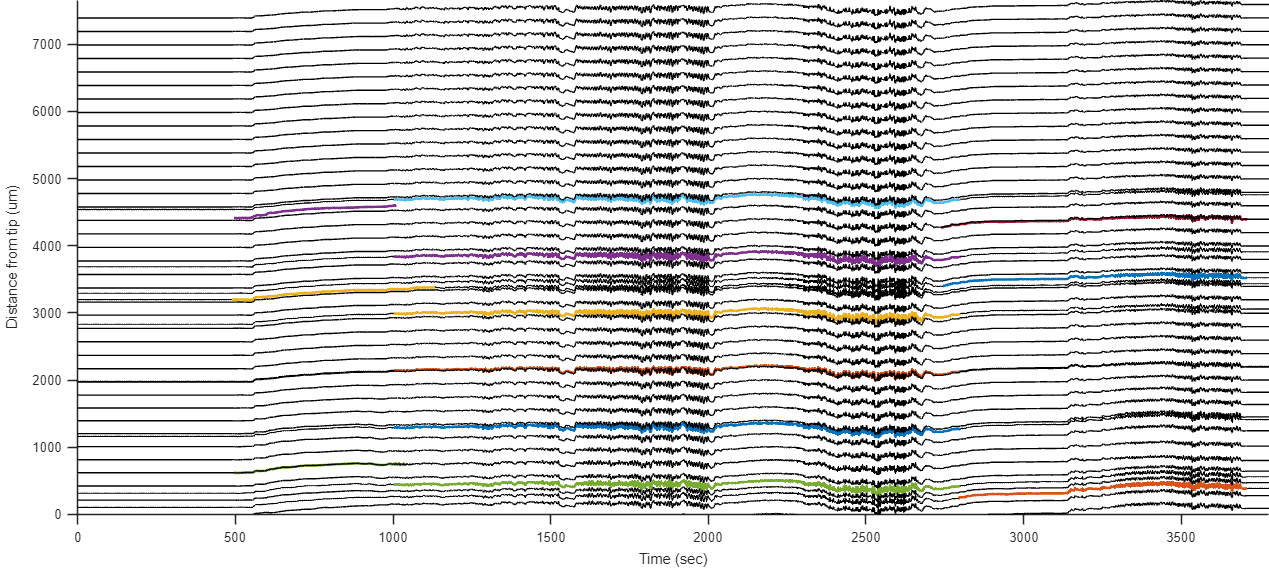

f = MPlot.Figure(311); clf
f.Position(3:4) = [1600 720];
% f.Visible = 'on';

NP.Motion.PlotTraces(tbTrExt.time, tbTrExt.Y, [0 0 0], 'LineWidth', 1);
NP.Motion.PlotTraces(tbTr.time, tbTr.Y);

[Tq, Yq, dYq] = F2.ComputeDispField();
plot(Tq, Yq, 'Color', [0 0 0 .25], 'HitTest', 'off');

xlim(tWin)
ylim([0 yEnd])

## Test correction on anchor traces

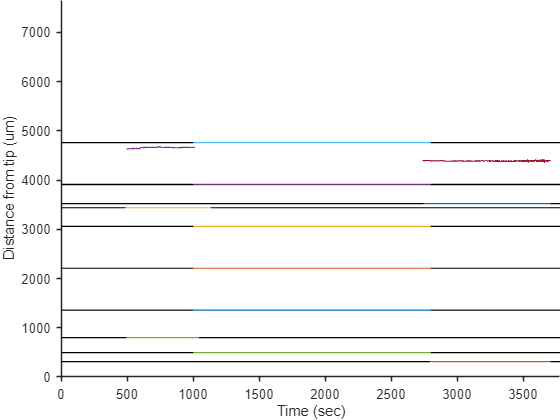

MPlot.Figure(410); clf

tbTrExtK = tbTrExt;
tbTrExtK.Y = F2.CorrectDepths(t, tbTrExt.Y);
NP.Motion.PlotTraces(tbTrExtK.time, tbTrExtK.Y, 'k', 'LineWidth', 1);

tbTrK = tbTr;
tbTrK.Y = F2.CorrectDepths(t, tbTr.Y);
NP.Motion.PlotTraces(tbTrK.time, tbTrK.Y, 'LineWidth', 1);

axis tight xy
ax = gca;
ax.LooseInset = [0 0 0 0];
ax.YLim = [0 yEnd];